emails = readtable("emails.csv", ReadRowNames=true, ReadVariableNames=true, VariableNamingRule="preserve");

k = [1 3 5 7 10];
acc = arrayfun(@(k) test_5fold_knn_acc(k, emails), k)

acc =     0.8329    0.8419    0.8413    0.8451    0.8513


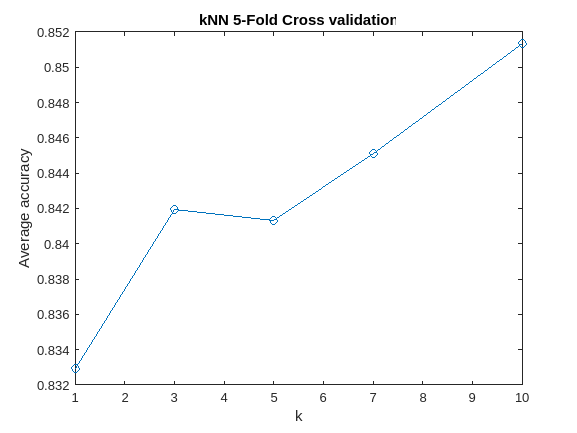

plot(k, acc, '-o')
title('kNN 5-Fold Cross validation')
xlabel('k');
ylabel('Average accuracy')
exportgraphics(gcf, 'hw3_4.pdf', ContentType='vector')

function accuracy = test_knn_acc(k, train_data, test_data) 
    mdl = fitcknn(train_data, 'Prediction', Distance='euclidean', NumNeighbors=k);
    pred = predict(mdl, test_data(:, 1:end-1));
    ind_pred = pred == 1;
    ind_y = table2array(test_data(:,end)) == 1;

    accuracy = sum(ind_pred == ind_y) / length(ind_y);
end

function accuracy = test_5fold_knn_acc(k, emails) 
    fold1_test = emails(1:1000,:);
    fold1_train = emails(1001:end,:);
    fold2_test = emails(1000:2000,:);
    fold2_train =emails([1:999, 2001:end], :);
    fold3_test = emails(2000:3000,:);
    fold3_train =emails([1:1999, 3001:end], :);
    fold4_test = emails(3000:4000,:);
    fold4_train =emails([1:2999, 4001:end], :);
    fold5_test = emails(4000:end,:);
    fold5_train =emails(1:3999, :);
    
    accuracy1 = test_knn_acc(k, fold1_train, fold1_test);
    accuracy2 = test_knn_acc(k, fold2_train, fold2_test);
    accuracy3 = test_knn_acc(k, fold3_train, fold3_test);
    accuracy4 = test_knn_acc(k, fold4_train, fold4_test);
    accuracy5 = test_knn_acc(k, fold5_train, fold5_test);

    accuracy = (accuracy1 + accuracy2 + accuracy3 + accuracy4 + accuracy5) ./ 5;
end
